# Lab 2 - Noise Removal

## Part 1

### Step 1

The following cell simply goes through some set-up and loads edge and noise filters. It reads in the same image that was used for the Lab 1.

% Clear the variables
clear

% Load variables
load sobel
load roberts
load filters
who


Your variables are:

difference_gradient_filterX             difference_gradient_filterY             first_order_gaussian_filter_1d_length5  gaussian_filter_1d_length5              gaussian_filter_3x3                     gaussian_filter_5x5                     laplacian                               mean_filter_3x3                         mean_filter_5x5                         robertsA                                robertsB                                sobelX                                  sobelY                                  




% Read the provided "shakey" image
shakey = read_image('', 'shakey.150.gif');

The following cell convolves a 3x3 Gaussian filter and 5x5 Gaussian filter with the shakey image and outputs the result.

**Question**: can you see any difference between them?

**Answer**: the convolved image with the 5x5 filter is more blurry, thus smoother, than with the 3x3 filter. This is because a larger filter is applied to a larger local area and it makes it more similar to the surrounding pixels because more pixels influence the convolved value than a few specific ones.

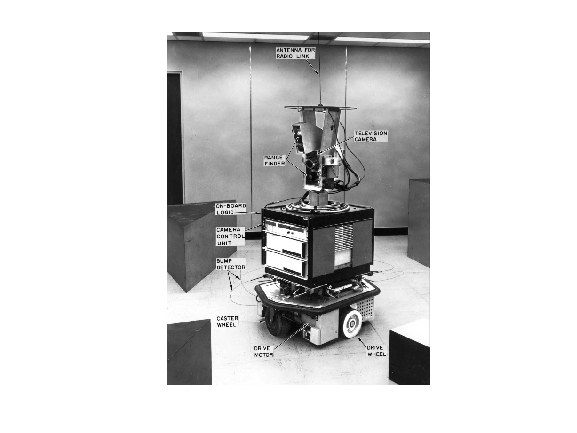

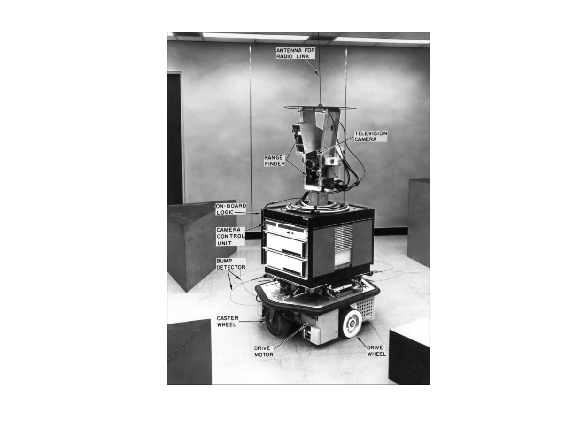

% Acquire maps after applying Gaussian filters
gaussian_3x3_map = conv2(gaussian_filter_3x3, shakey);
gaussian_5x5_map = conv2(gaussian_filter_5x5, shakey);

% Show the acquired maps
show_image(gaussian_3x3_map, "gaussian_3x3_map")
show_image(gaussian_5x5_map, "gaussian_5x5_map")

The following cell convolves a horizontal *Sobel *filter with both Gaussian maps and shows the results.

**Task**: try applying an edge filter to each and thresholding.

**Results**: the map that was acquired by applying a 5x5 Gaussian filter has less noise. This is due to the fact that the larger filter smoothens the image better than the small filter (i.e., the same reason as above).

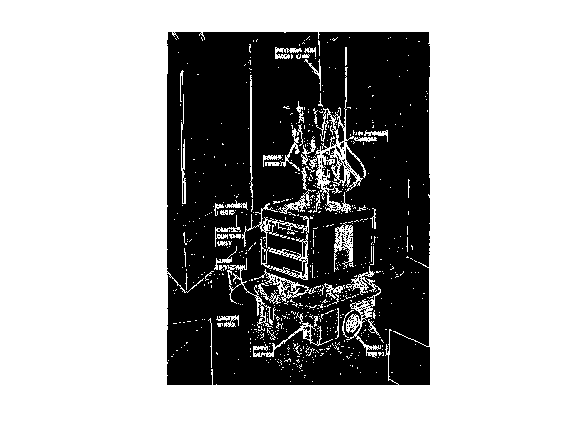

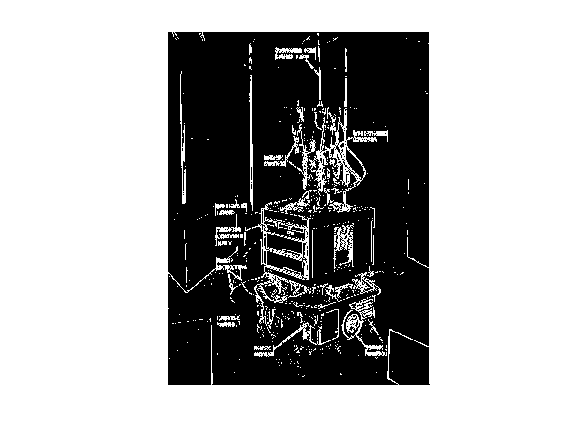

% Apply an edge filter (Sobel horizontal) to the Gaussian maps
gaussian_3x3_edge_map = conv2(sobelX, gaussian_3x3_map);
gaussian_5x5_edge_map = conv2(sobelX, gaussian_5x5_map);

% Show the acquired maps with a threshold of 40
show_image(abs(gaussian_3x3_edge_map) > 40, "gaussian_3x3_sobelX_map")
show_image(abs(gaussian_5x5_edge_map) > 40, "gaussian_5x5_sobelX_map")

### Task 1

The following cell simply outputs the result of a plain horizontal Sobel filter applied directly to the image and thresholded by 40.

**Question**: can you describe the effect in comparison with applying the edge filter to the image directly?

**Answer**: considering the same threshold, if we we apply the edge filter directly on the image, there will be more noise in the acquired map, i.e., visually more false positives are captured as edges. In contrast, smoothening the image with a Gaussian filter prior to applying an edge filter averages the noise out and keeps the edges more standing out.

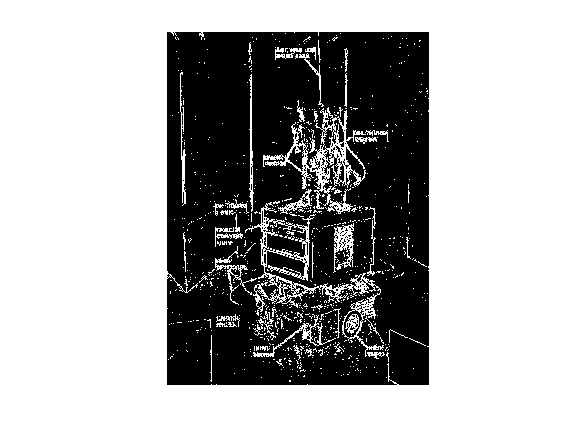

% Apply edge filter (Sobel horizontal) directly on the image
edge_map = conv2(sobelX, shakey);

% Show the acquired edge map
show_image(abs(edge_map) > 40, "sobelX_map")

## Part 2

### Step 2 & Task 2

The following cell provides interaction tools to play around with Gaussian maks. It checks how the output depends on the size of the Gaussian filter, the standard deviation and the range factor. It also checks how it affect edge detection.

**Question**: what happens to the image as you increase the size of the mask? What happens as you increase the size of s?

**Answer**: as we increase the size of the mask, the image becomes more blurry (similar reason explained above). As we increase sigma, the image also becomes more blurry because the weight values become more spread around the mean, thus surrounding cells play a bigger role in the local area when it is convolved with the kernel.

**Question**:  what happens to the edges in the heavily blurred case after applying gradient operators, such as Sobel operators?

**Answer**: thicker edges stand out more and thinner edges almost disappear. This is because thin edges may sometime be confused with noise which gets averaged out after heavily blurying an image. Stron edges, on the other hand remain standing out therefore the gradient operator captures the changes and emphasizes them.

**Question**: what is the effect of increasing the size of the Gaussian Filter (3x3 versus 5x5 for example)?

**Answer**: this was answered above. In the particular case of 3x3 vs 5x5, 3x3 filter leaves more details (thus more noise) than 5x5. So the image with 3x3 filter is less blurry. It can also be seen that, after applying the threshold, there are more false positives in the backround captured, but also more true positiives within thin edges.

**Question**: what is the effect of changing the standard deviation s? Why do you see what you see?

**Answer**: this answerd was answered above.

% Allow to interact with sigma, size and factor values
sigma = 3;
size = 3;
factor = 1;

% Create Gaussian filter based on those values
gaussian_filter = create_gaussian_mask(0, sigma, size, factor)

gaussian_filter =     0.0158    0.0167    0.0158
    0.0167    0.0177    0.0167
    0.0158    0.0167    0.0158


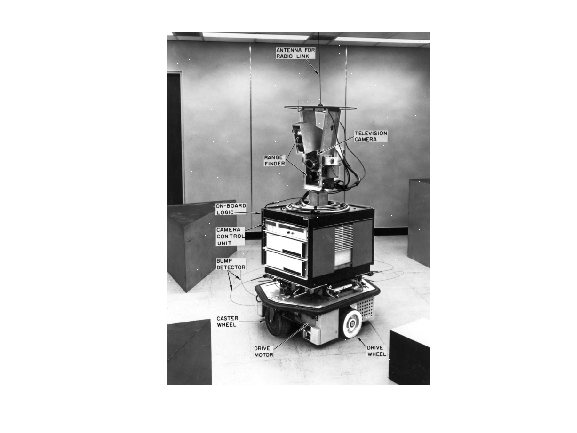

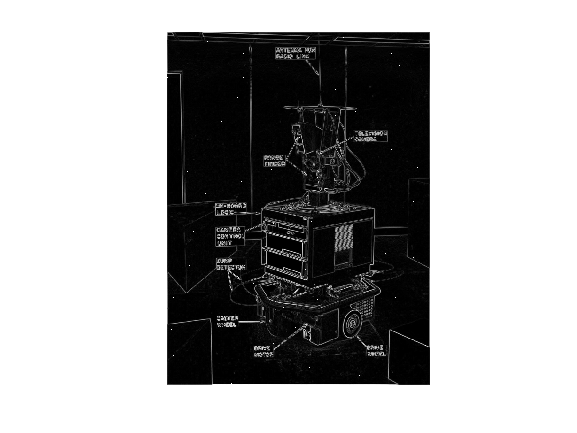


% See what happens to the image after applying the filter
gaussian_map = conv2(gaussian_filter, shakey);
show_image(gaussian_map)

% Calculate edge gradient maps on Gaussian maps
gaussian_sobelX_map = conv2(sobelX, gaussian_map);
gaussian_sobelY_map = conv2(sobelY, gaussian_map);
gaussian_sobel_map = magnitude(gaussian_sobelX_map, gaussian_sobelY_map);
show_image(gaussian_sobel_map)

## Part 3

### Step 3

The following cell performs a time test to check performance between 2 1D and 1 2D convolution operations.

**Question**: can you detect differences in the CPU times as the mask sizes increase?

**Answer**: for small matrix size (3, 5 and 7) 1 2D convolution performs faster than 2 1D convolutions. However for the kernel sizes of 9 and above, the time taken to perform the convolution for a 2D case dramatically increases compared to 1D case (e.g., twice the duration when filter size is 15).

**Question**: are there any effects due to small floating point errors?

**Answer**: there are very small relative errors, i.e., the range is from 1e-16 to 1e-18. This means the concolution result is almost the same.

% Init filter size range
Ms = 3:2:15;

% Init values
t1s = Ms;
t2s = Ms;
rel_errs = Ms;

for M=Ms
    % Create 2 1D and 1 2D large Gaussian filters
    gaussian_1xM_custom = N(0, 2, -floor(M/2):floor(M/2));
    gaussian_Mx1_custom = N(0, 2, -floor(M/2):floor(M/2))';
    gaussian_MxM_custom = create_gaussian_mask(0, 2, M);

    % Get the median time taken to convolve the image with 2 1D filters
    t1 = @() apply_2_1d_gaussians(gaussian_1xM_custom, gaussian_Mx1_custom, shakey);
    t1s(floor((M-3)/2)+1) = timeit(t1);

    % Get the median time taken to convolve the image with 1 2D filter
    t2 = @() apply_1_2d_gaussian(gaussian_MxM_custom, shakey);
    t2s(floor((M-3)/2)+1) = timeit(t2);

    % Get the actual outputs for 2 1D and 1 2D convolutions to compare them
    gaussian_map_2_filters = apply_2_1d_gaussians(gaussian_1xM_custom, gaussian_Mx1_custom, shakey);
    gaussian_map_1_filter = apply_1_2d_gaussian(gaussian_MxM_custom, shakey);

    % Check the relative error between the 2
    [~, rel_err] = calc_error(gaussian_map_2_filters, gaussian_map_1_filter);
    rel_errs(floor((M-3)/2)+1) = rel_err;
end

% Display whether the errors between convolved maps are low and acceptable
disp(strcat("Relative errors range from ", num2str(min(rel_errs)), " to ", num2str(max(rel_errs))))

Relative errors range from 7.3243e-17 to 3.9102e-16


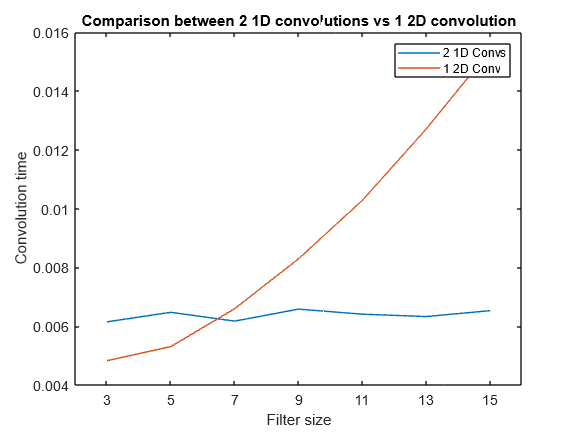


% Plot the 2 plots
plot(Ms, t1s, Ms, t2s)
title("Comparison between 2 1D convolutions vs 1 2D convolution");
legend("2 1D Convs", "1 2D Conv");
xlabel("Filter size");
ylabel("Convolution time");
xticks(Ms);

### Step 4

The following cell produces an edge map after applying a Laplacian filter where edges are determined by zerocrossing.

**Question**: why does it produce a poor result compared to the other operators?

**Answer**: the poor result is due to finite difference approximation. In other words, it is not always clear where exactly the edge is, it could be one pixel further or closer. It is because zero crossing determines a thin line between pixels with values with opposing signs and the values themselves could be close to 0 meaning higher uncertainty.

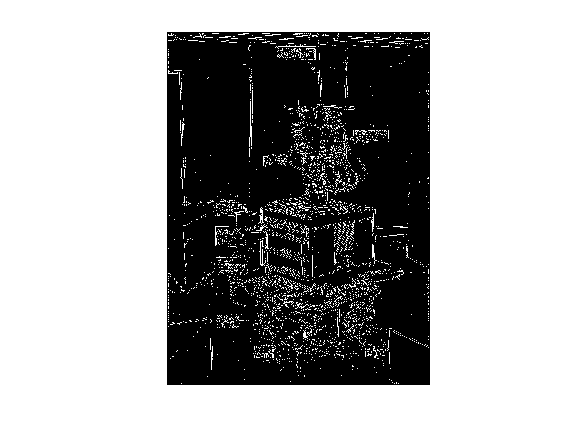

% Convolve with laplacian and apply zerocross
I_in = conv2(shakey, laplacian);
I_out = edge(I_in, 'zerocross');

% Show the result
show_image(I_out, "laplacian_zerocross")

### Task 3

The following cell produces a Laplacian of Gaussian filter and applies it to an image.

**Question**: How could you combine the idea of the Laplacian operator with the idea of Gaussian smoothing?

**Answer**: first we find the gradient of the Gaussian kernel (via convolution with laplacian filter). Then we take the LoG  filter, apply it to the image and then apply the zerocrossing to determine the edges. It still doesn't produce great results due to the reason above.

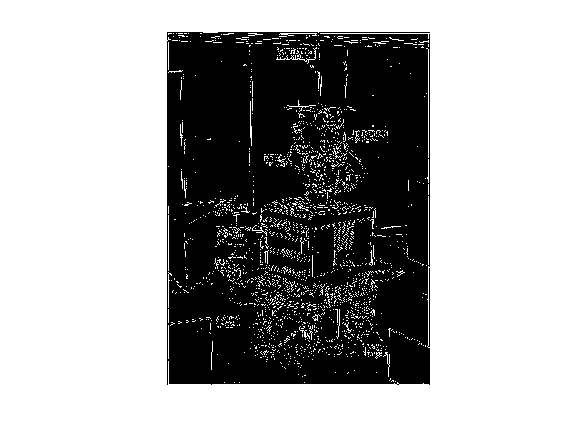

% Get LoG filter, apply to image and apply zerocross
log_filter = conv2(laplacian, gaussian_filter_5x5);
I_in = conv2(log_filter, shakey);
I_out = edge(I_in, 'zerocross');

% Show the result
show_image(I_out, "log_zerocross")